# Aula 6 - Laboratório de Controle - 2021/1

## Métodos de sintonia dos ganhos do controlador PID

## Nome: Arthur Lorencini Bergamaschi

I=1 ; 
turma=2 ;
W=[4 8 2 11 5 3 12 9 1 6 7 10;9 7 2 8 4 12 6 3 5 10 11 1;
     6 12 9 8 10 7 2 4 1 3 5 11;10 11 7 3 1 2 8 12 5 9 6 4;1 10 5 3 11 7 9 12 4 8 2 6]';
g=tf(0.9*I^4,poly(-[1 1 1 1]*I));

## Atividade 1 - Obtenção de modelos de ordem 1

Os comandos abaixo geram 13 modelos de ordem 1 para diferentes atrasos. Analise os gráficos gerados nas figura 1 e 2 e responda as perguntas 1.1 a 1.3.

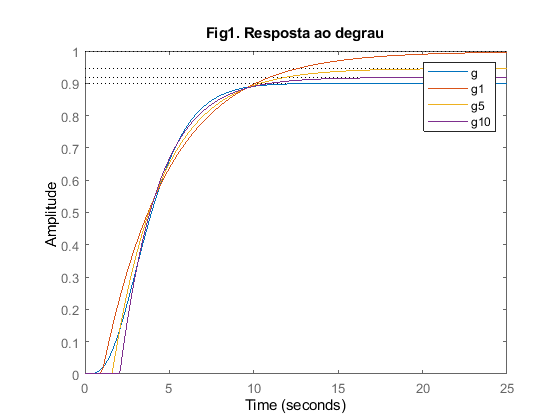

[delay, tau, K, fit, Kp]=funcao_g1(g);
g1=tf(K(1),[tau(1) 1],'InputDelay', delay(1));
g5=tf(K(5),[tau(5) 1],'InputDelay', delay(5));
g10=tf(K(10),[tau(10) 1],'InputDelay', delay(10));
figure;
step(g,g1,g5,g10);legend('g','g1','g5','g10');title('Fig1. Resposta ao degrau');

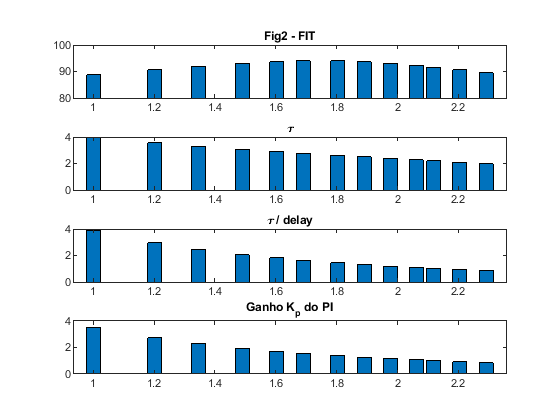


figure;
subplot(4,1,1);bar(delay,fit);title('Fig2 - FIT');ylim([80 100])
subplot(4,1,2);bar(delay,tau);title('\tau'); 
subplot(4,1,3);bar(delay,tau./delay);title('\tau / delay'); 
subplot(4,1,4);bar(delay,Kp);title('Ganho K_p do PI')

A Tabela 1 mostra como são calculados os ganhos dos controladores P, PI ou PID usando o método de Ziegler-Nichols 

usando um modelo de primeira ordem definido por $G(s)=\frac{Ke^{-\theta}}{\tau s + 1}$. Dica:$K_i=1/T_{i}$ e $K_d=T_d$.

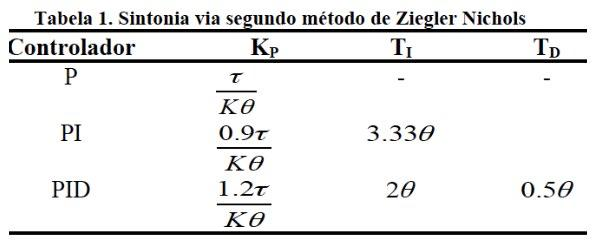

1.1 Que valor de delay dá o maior fit? Qual o fit?

O delay que dá o maior fit é o 1.7s. O seu fit é de 94.

1.2 Explique o comportamento da relação tau/delay usando as figuras 1 e 2.

Sabemos que, ao aumentar o delay (tempo morto), o tau tende a diminuir. Analisando a figura, o g10 tem o maior delay, logo, faz a relação diminuir. E além disso, o g10 é o modelo que tem a subida mais rápida, logo os dois tempos fazem a relação diminuir.

1.3 Use a Tabela 1 para explicar o efeito de tau/delay sobre o ganho Kp do controlador (ver fig 2)

Se for utilizado o método ZN, vemos que tau é diretamente proporcional ao Kp, logo, quanto menor o valor de tau, menor o valor de Kp.

## Atividade 2 - Efeito da relação tau/delay na sintonia do controlador

Nesta atividade são avaliados os 13 modelos gerados na atividade 1 para o projeto de um controlador PI via método  ZN (Tabela 1). 

A escolha do modelo é baseada em seu fit e também na boa resposta ao degrau obtida para  o controlador resultante (Ver Fig.3 ). Observe que o controlador 

é sempre testado na FT original g, e não no modelo usado para o projeto.

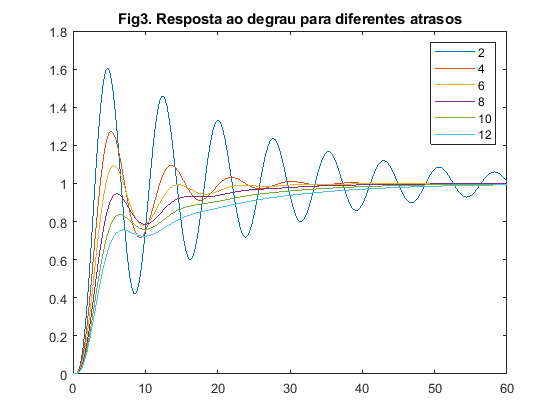

Tempo=60  ;
t=linspace(0,Tempo,250);
Y=[];
for i=1:13
    g1=tf(K(i),[tau(i) 1],'InputDelay', delay(i));
    c1=sintonia(g1,'PI', 'zie');
    m1=feedback(c1*g,1);
    
    y=step(m1,t);
    Y=[Y y];
    Iae(i) = iaeupts(m1,t);
end;

figure;
plot(t,Y(:,[2 4 6 8 10 12]));
legend('2','4','6','8','10','12');
title('Fig3. Resposta ao degrau para diferentes atrasos')

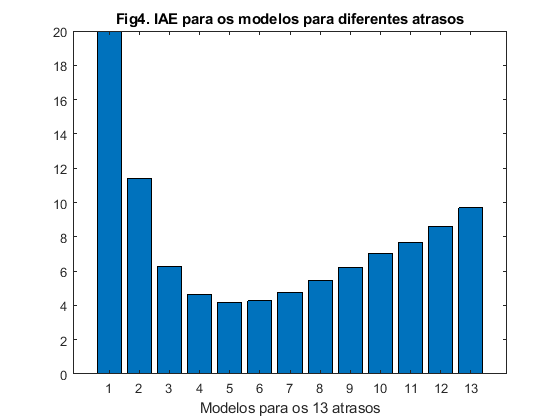


figure;
bar(Iae); ylim([0 20])
title('Fig4. IAE para os modelos para diferentes atrasos')
xlabel('Modelos para os 13 atrasos')

2.1 Qual o efeito de tau/delay no tempo de subida e sobreelevação? (Ver Kp na figura 2 e efeito na Figura 3)

Quanto maior o valor da relação tau/delay, mais rápido é a subida e maior também será a sua elevação. Basta ver que na primeira curva, em que a relação é maior (perante a figura 2), é a curva que sobe mais rápido e que tem maior sobreelevação.

2.2 Baseado no IAE, qual o modelo mais adequado a ser utilizado e por quê? 

O modelo mais adequado é o quinto modelo, pois para o mesmo instante de tempo avaliado, temos um valor de IAE menor.

## Atividade 3 - Escolha do método de sintonia que dá o melhor controlador PI

Escolha o modelo g1 que será usado daqui para diante, usando as figuras das atividades 1 e 2, e definindo i na próxima linha. Este modelo será usado para projetar o controlador usando 4 métodos de sintonia.

## IMPORTANTE: Para avançar mostre ao professor o resultado das atividades 1 e 2 

## e justifique sua decisão pelo modelo a ser usado

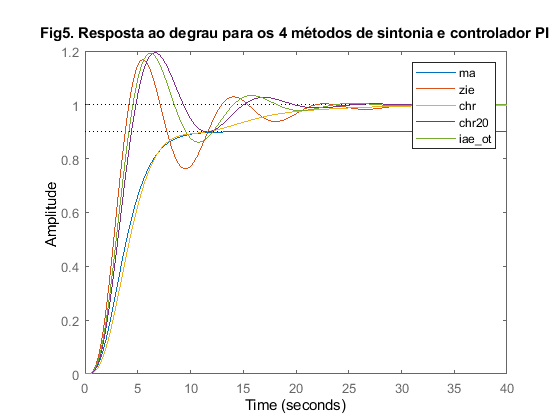

i=5;
g1=tf(K(i),[tau(i) 1],'InputDelay', delay(i));
c1=sintonia(g1,'PI', 'zie');
c2=sintonia(g1,'PI', 'chr');
c3=sintonia(g1,'PI', 'chr20');
c4=sintonia(g1,'PI', 'iae_ot');

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);
m4=feedback(c4*g,1);

figure
Tempo=40; 
t=linspace(0,Tempo,250); 
step(g,m1,m2,m3,m4,Tempo);title('Fig5. Resposta ao degrau para os 4 métodos de sintonia e controlador PI');
legend('ma','zie','chr','chr20','iae_ot')

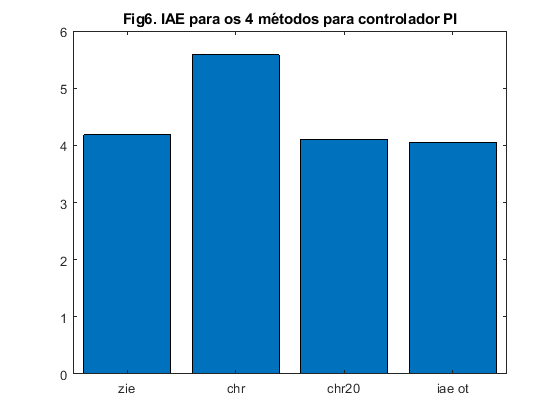

iae_pi=[iaeupts(m1,t) iaeupts(m2,t) iaeupts(m3,t) iaeupts(m4,t)];

leg1 = categorical({'zie','chr','chr20','iae ot'});
leg2 = reordercats(leg1,{'zie','chr','chr20','iae ot'});
figure;
bar(leg2,iae_pi);title('Fig6. IAE para os 4 métodos para controlador PI'); 
set(gca,'xticklabel',{'zie','chr','chr20','iae ot'});

3.1 Compare o IAE obtido pelos diferentes métodos e explique o motivo de valores altos de IAE observando a resposta ao degrau na figura 5

o 'chr' possui o maior valor de IAE pois o seu tempo de subida é o maior de todos e isso é um dos maiores fatores para fazer o valor de IAE aumentar, conforme mostra a respota ao degrau na figura 5.

## Atividade 4 - Escolha do método que dá o melhor controlador PID

Agora o controlador PID é selecionado para os 4 projetos.

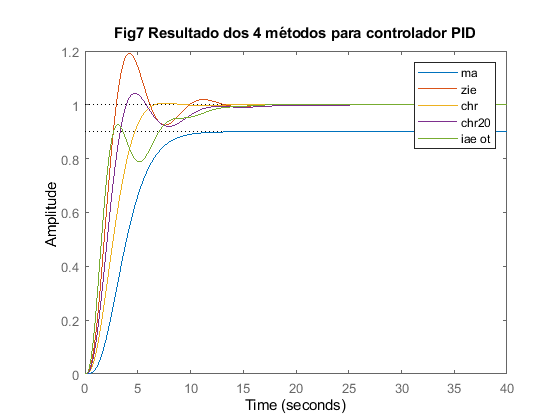

c1=sintonia(g1,'PID', 'zie');
c2=sintonia(g1,'PID', 'chr');
c3=sintonia(g1,'PID', 'chr20');
c4=sintonia(g1,'PID', 'iae_ot');

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);
m4=feedback(c4*g,1);

iae_pid=[iaeupts(m1,t) iaeupts(m2,t) iaeupts(m3,t) iaeupts(m4,t)];

figure
step(g,m1,m2,m3,m4,Tempo);
title('Fig7 Resultado dos 4 métodos para controlador PID');
legend('ma','zie','chr','chr20','iae ot')

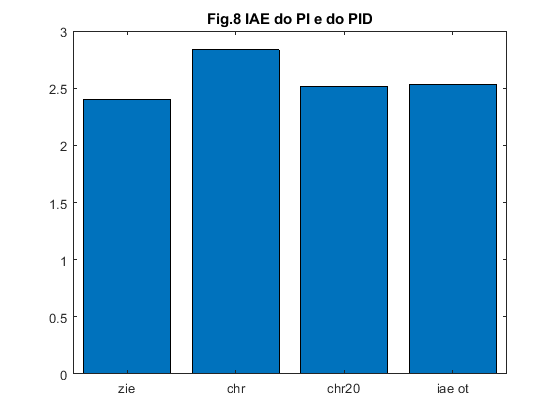


leg1 = categorical({'zie','chr','chr20','iae ot'});
leg2 = reordercats(leg1,{'zie','chr','chr20','iae ot'});

figure;
bar(leg2,iae_pid);
title('Fig.8 IAE do PI e do PID');

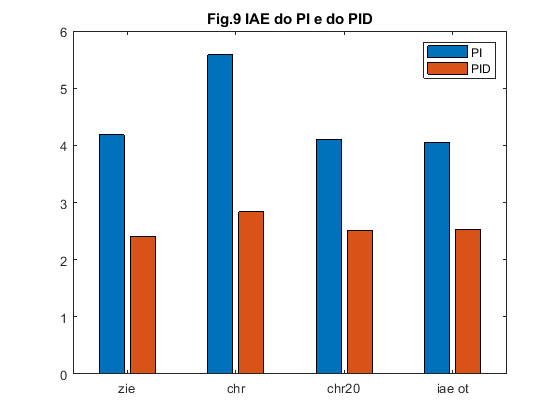



figure;
bar(leg2,[iae_pi; iae_pid]);
legend('PI','PID');title('Fig.9 IAE do PI e do PID');

4.1 Compare os valores de IAE do PID (Fig 8) obtido pelos diferentes métodos e explique o motivo de valores altos de IAE observando a resposta ao degrau na figura 7

Novamente, o 'chr' é o que possui maior IAE pois o seu tempo de subida é o maior de todos, conforme a figura 7. Os outros 3, possuem tempos de subidas idênticos, o que só diferencia eles é a sobreelevação.

4.2 Compare o desempenho dos controladores PI e PID (Fig.9) em termos dos valores de IAE para os 4 métodos, usando as figuras de resposta ao degrau para justificar

Vemos que ao adicionar o fator kd, diminuimos drasticamente o valor do IAE. Pois ele consegue diminuir o tempo de estabelecimento e atenunar algumas das sobreelevações. Além disso, visualisando as figuras, dá para observar que ele consegue reduzir um pouco também o tempo de subida, portanto, faz o IAE dimunir mais ainda.

## Atividade 5 - Avaliação da sintonia lambda com controlador PID

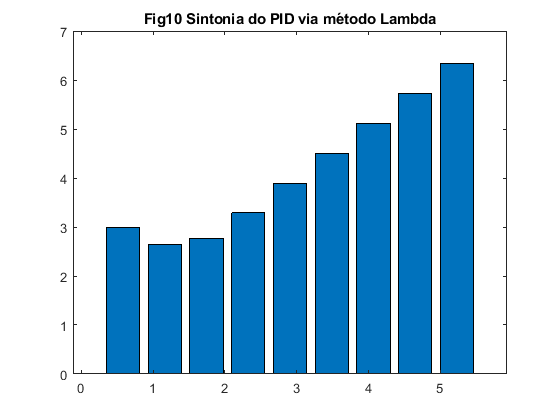

tau=g1.Denominator{1}(1);
lambda=tau*[0.2 0.4 0.6 0.8 1 1.2 1.4 1.6 1.8]; % Altere se ficar melhor
for i=1:length(lambda)
    c=sintonia(g1,'PID', 'lam',lambda(i));
    m=feedback(c*g,1);
    iael(i)=iaeupts(m,t);
end

figure
bar(lambda,iael);title('Fig10 Sintonia do PID via método Lambda');

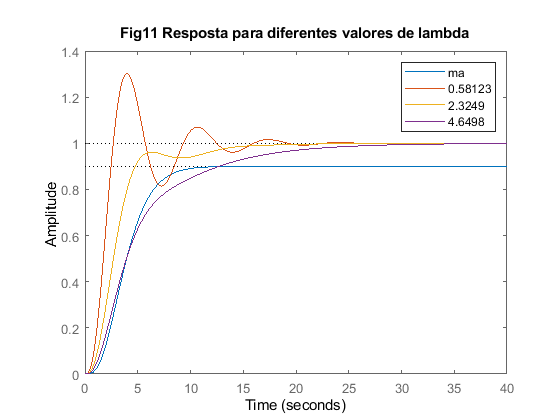


c1=sintonia(g1,'PID', 'lam',lambda(1));
c2=sintonia(g1,'PID', 'lam',lambda(4));
c3=sintonia(g1,'PID', 'lam',lambda(8));

m1=feedback(c1*g,1);
m2=feedback(c2*g,1);
m3=feedback(c3*g,1);

figure
step(g,m1,m2,m3,Tempo);title('Fig11 Resposta para diferentes valores de lambda')
legend('ma',num2str(lambda(1)),num2str(lambda(4)),num2str(lambda(8)))

5.1 Compare o desempenho dos controladores PID variando lambda com os controladores obtidos pelos outros métodos e justifique o resultado. Que valor de lambda deu menor IAE? Compare com o IAE ótimo e explique como obter o menor IAE com o método lambda.

Valor de lambda igual a 1.16 é o que gera o menor IAE, de 2.65. Vemos que o um lambda maior implica numa resposta lenta.

5.2 Qual o efeito na resposta em malha fechada de pequenos valores de lambda na sintonia do controlador? Por que?

Para menores valores de lambda, temos uma subida mais rápida, pois o lambda é equivalente a constante de tempo, conforme explicado no material auxiliar.

datetime('now')

ans = datetime
   21-Jul-2021 22:08:14


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Aula6'